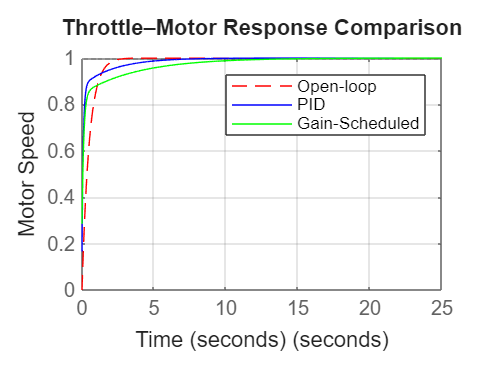

% compare_results.m
% Compare open-loop, PID, and gain-scheduled responses

clc;
clear;
close all;

% === PLANT ===
K = 1;
tau = 0.5;
G = tf(K, [tau 1]);

% === PID CONTROLLER (use your tuned values) ===
Kp = 6;
Ki = 3;
Kd = 0.1;

C = pid(Kp, Ki, Kd);
T_pid = feedback(C * G, 1);

% === GAIN-SCHEDULED (use highest zone as representative) ===
C_gs = pid(5, 1.5, 0.2);
T_gs = feedback(C_gs * G, 1);

% === PLOT ===
figure;
step(G, 'r--'); hold on;
step(T_pid, 'b-');
step(T_gs, 'g-');

grid on;
legend('Open-loop', 'PID', 'Gain-Scheduled');
title('Throttle–Motor Response Comparison');
xlabel('Time (seconds)');
ylabel('Motor Speed');

% === SAVE PATH ===
save_path = 'C:\Users\SABEE\OneDrive\Desktop\Attachments\Desktop\sabeeh\My projects\Control systems\end_eval';

if ~exist(save_path, 'dir')
    mkdir(save_path);
end

saveas(gcf, fullfile(save_path, 'comparison_plot.png'));